
Matyas, x0 = [-4 4]


            Parametr                       Bez_ograniczen                          Z_ograniczeniami           
    ________________________    _____________________________________    _____________________________________

    "Algorytm"                  "interior-point"                         "interior-point"                     
    "TolX"                      "1e-10"                                  "1e-10"                              
    "TolFun"                    "1e-06"                                  "1e-06"                              
    "MaxIter"                   "1000"                                   "1000"                               
    "x"                         "[0 0]"                                  "[-3.7782e-09 3.7782e-09]"           
    "fval"                      "0"                                      "1.4274767e-17"                      
    "iter

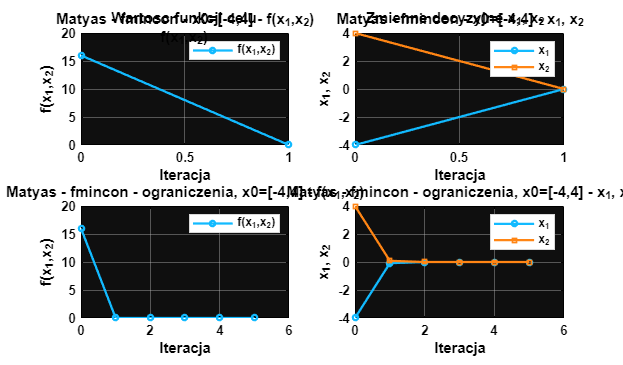


Matyas, x0 = [2 2]


            Parametr                       Bez_ograniczen                          Z_ograniczeniami           
    ________________________    _____________________________________    _____________________________________

    "Algorytm"                  "interior-point"                         "interior-point"                     
    "TolX"                      "1e-10"                                  "1e-10"                              
    "TolFun"                    "1e-06"                                  "1e-06"                              
    "MaxIter"                   "1000"                                   "1000"                               
    "x"                         "[-2.42544e-07 -1.70754e-07]"            "[-3.49505e-09 -3.49505e-09]"        
    "fval"                      "2.99658728e-15"                         "4.88613693e-19"                     
    "iter

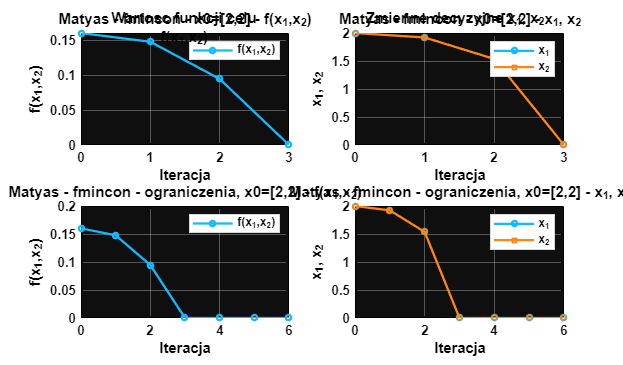


Matyas, x0 = [4 -4]


            Parametr                       Bez_ograniczen                          Z_ograniczeniami           
    ________________________    _____________________________________    _____________________________________

    "Algorytm"                  "interior-point"                         "interior-point"                     
    "TolX"                      "1e-10"                                  "1e-10"                              
    "TolFun"                    "1e-06"                                  "1e-06"                              
    "MaxIter"                   "1000"                                   "1000"                               
    "x"                         "[0 0]"                                  "[3.7782e-09 -3.7782e-09]"           
    "fval"                      "0"                                      "1.4274767e-17"                      
    "iter

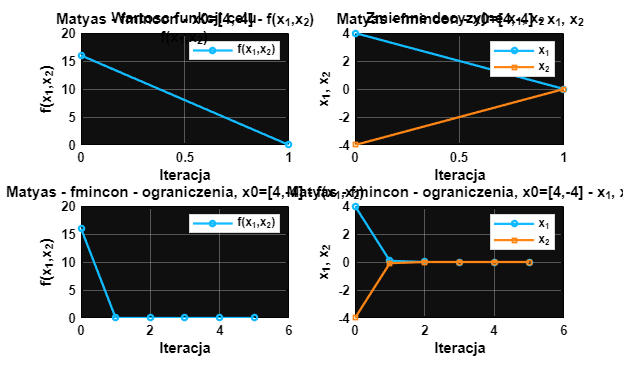

clear; clc; close all;

%% Funkcje testowe
f1 = @(x) 0.26*(x(1)^2+x(2)^2)-0.48*x(1)*x(2);
f2 = @(x) 0.5*(x(1)^4-16*x(1)^2+5*x(1)+x(2)^4-16*x(2)^2+5*x(2));
g1 = @(x) [0.52*x(1)-0.48*x(2); 0.52*x(2)-0.48*x(1)];
g2 = @(x) [2*x(1)^3-16*x(1)+2.5; 2*x(2)^3-16*x(2)+2.5];
H1 = @(x) [0.52 -0.48; -0.48 0.52];
H2 = @(x) [6*x(1)^2-16 0; 0 6*x(2)^2-16];

%% Punkty startowe i ograniczenia
funkcja = 1;  % 1 - Matyas, 2 - Styblinski-Tang
if funkcja == 1
    f = f1; g = g1; H = H1; nazwa = 'Matyas';
    X0 = [-4 4; 2 2; 4 -4];
    lb = [-10 -10]; ub = [10 10];
else
    f = f2; g = g2; H = H2; nazwa = 'Styblinski-Tang';
    X0 = [-4 -4; 4 4; -4 4];
    lb = [-5 -5]; ub = [5 5];
end

opts = optimoptions('fmincon','Algorithm','interior-point', ...
    'Display','off','OutputFcn',@historia);
tol = [1e-10 1e-6 1000 3000];
pola = ["Algorytm";"TolX";"TolFun";"MaxIter";"x";"fval"; ...
        "iteration";"Func-count";"First order optimality"; ...
        "Warunek stopu";"Gradient";"Hesjan";"Feasibility"];

%% Optymalizacja z ograniczeniami i bez ograniczen
for k = 1:3
    x0 = X0(k,:);
    [xa,fa,flaga,outa] = fmincon(f,x0,[],[],[],[],[],[],[],opts);
    ha = historia();
    ha = [0 x0 f(x0); ha(ha(:,1)>0,:)];

    [xb,fb,flagb,outb] = fmincon(f,x0,[],[],[],[],lb,ub,[],opts);
    hb = historia();
    hb = [0 x0 f(x0); hb(hb(:,1)>0,:)];

    t1 = zapis(tol,xa,fa,flaga,outa,g(xa),H(xa));
    t2 = zapis(tol,xb,fb,flagb,outb,g(xb),H(xb));
    fprintf('\n%s, x0 = [%g %g]\n',nazwa,x0);
    disp(table(pola,t1,t2, ...
        'VariableNames',{'Parametr','Bez_ograniczen','Z_ograniczeniami'}));

    opisA = sprintf('x0=[%g,%g]',x0(1),x0(2));
    opisB = sprintf('ograniczenia, x0=[%g,%g]',x0(1),x0(2));
    figure('Color','w','Position',[100 100 1450 850]);
    rysuj(ha,hb,nazwa,opisA,opisB);
end


function [stop,h] = historia(x,ov,state)
persistent wyniki
stop = false;
if nargin == 0
    stop = wyniki;
    h = [];
    return
end
if strcmp(state,'init')
    wyniki = [0 x(:).' ov.fval];
elseif strcmp(state,'iter')
    p = [ov.iteration x(:).' ov.fval];
    if p(1) > wyniki(end,1)
        wyniki(end+1,:) = p;
    else
        wyniki(end,:) = p;
    end
end
h = [];
end

function w = zapis(tol,x,fval,flag,out,grad,H)
if flag == 0
    stop = 'Limit iteracji lub wywolan';
elseif flag == 2
    stop = 'Mala zmiana x';
else
    stop = 'Kryterium optymalnosci';
end
w = ["interior-point"; string(tol(1)); string(tol(2)); string(tol(3)); ...
    string(mat2str(x,6)); string(sprintf('%.9g',fval)); ...
    string(out.iterations); string(out.funcCount); ...
    string(sprintf('%.5g',max(abs(grad)))); ...
    string(sprintf('%s (exitflag=%d)',stop,flag)); ...
    string(mat2str(grad(:).',5)); string(mat2str(H,5)); "0"];
end

function rysuj(ha,hb,nazwa,opisS,opisC)
kolor1 = [0.07 0.73 1.00];
kolor2 = [1.00 0.52 0.08];

subplot(2,2,1);
plot(ha(:,1),ha(:,4),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fmincon - %s - f(x_1,x_2)',nazwa,opisS), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('f(x_1,x_2)','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('f(x_1,x_2)','TextColor','k','Color','w','Location','northeast');

subplot(2,2,2);
plot(ha(:,1),ha(:,2),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); hold on;
plot(ha(:,1),ha(:,3),'-s','Color',kolor2,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fmincon - %s - x_1, x_2',nazwa,opisS), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('x_1, x_2','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('x_1','x_2','TextColor','k','Color','w','Location','northeast');

subplot(2,2,3);
plot(hb(:,1),hb(:,4),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fmincon - %s - f(x_1,x_2)',nazwa,opisC), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('f(x_1,x_2)','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('f(x_1,x_2)','TextColor','k','Color','w','Location','northeast');

subplot(2,2,4);
plot(hb(:,1),hb(:,2),'-o','Color',kolor1,'LineWidth',1.7,'MarkerSize',4); hold on;
plot(hb(:,1),hb(:,3),'-s','Color',kolor2,'LineWidth',1.7,'MarkerSize',4); grid on;
title(sprintf('%s - fmincon - %s - x_1, x_2',nazwa,opisC), ...
    'Color','k','FontWeight','bold','FontSize',10);
ylabel('x_1, x_2','Color','k','FontWeight','bold');
xlabel('Iteracja','Color','k','FontWeight','bold');
legend('x_1','x_2','TextColor','k','Color','w','Location','northeast');

for ax = findall(gcf,'Type','axes')'
    ax.Color = [0.06 0.06 0.06];
    ax.XColor = [0 0 0]; ax.YColor = [0 0 0];
    ax.GridColor = [.72 .72 .72]; ax.GridAlpha = .42;
    ax.FontSize = 10; ax.FontWeight = 'bold';
    ax.Box = 'on';
    ax.Title.Color = [0 0 0];
    ax.XLabel.Color = [0 0 0]; ax.YLabel.Color = [0 0 0];
end

annotation('textbox',[.13 .954 .33 .033], ...
    'String','Wartosc funkcji celu f(x_1,x_2)', ...
    'Interpreter','tex','EdgeColor','none', ...
    'HorizontalAlignment','center','FontWeight','bold', ...
    'FontSize',11,'Color','k');
annotation('textbox',[.56 .954 .34 .033], ...
    'String','Zmienne decyzyjne x_1, x_2', ...
    'Interpreter','tex','EdgeColor','none', ...
    'HorizontalAlignment','center','FontWeight','bold', ...
    'FontSize',11,'Color','k');
end
